% Maxwell Greene
% April 8th, 2018
% Math Programming Homework #7

%%
%Question #1
disp('Question #1:');

Question #1:


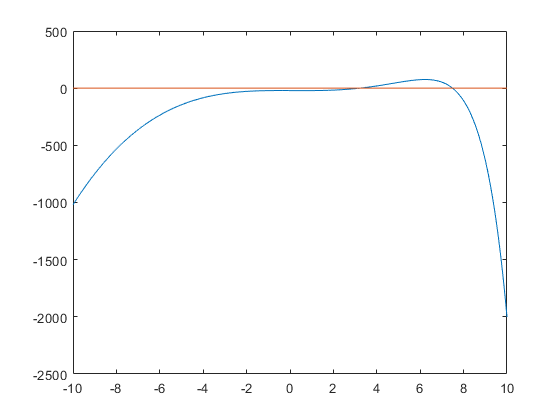


f = @(x) x.^3 - exp(0.8*x)-20;

x1 = linspace(-10,10,1001);
y1 = f(x1);
zero1 = 0.*x1;
figure(); plot(x1,y1,x1,zero1);

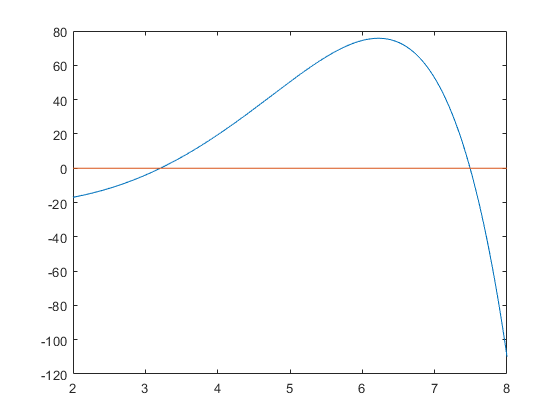

    
    %Use this to estimate a better domain...

x2 = linspace(2,8,1001);
y2 = f(x2);
zero2 = 0.*x2;
figure(); plot(x2,y2,x2,zero2);


disp(' This function has 2 solutions.');

 This function has 2 solutions.


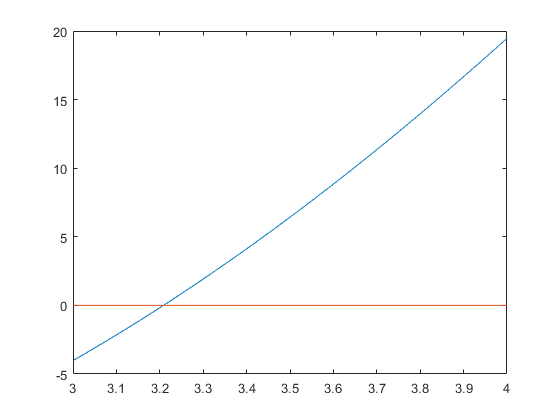


    %Now that we have a good idea of where the two zero values are, we isolate
    %them...

x3 = linspace(3,4,101);
y3 = f(x3);
zero3 = 0.*x3;
figure(); plot(x3,y3,x3,zero3);

fzero3_4 = fzero(f,3);
disp(['  f(x) = 0 at x = ' , num2str(fzero3_4)]);

  f(x) = 0 at x = 3.2082


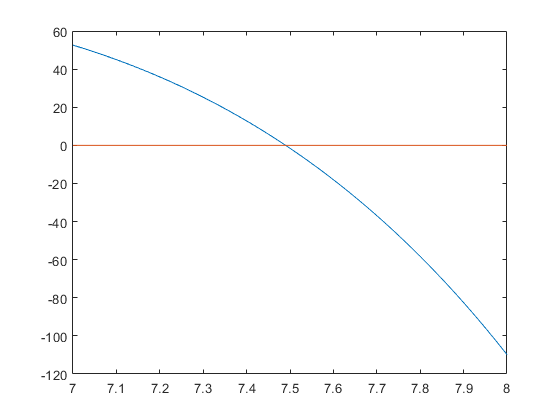


x4 = linspace(7,8,101);
y4 = f(x4);
zero4 = 0.*x4;
figure(); plot(x4,y4,x4,zero4);

fzero7_8 = fzero(f,7);
disp(['  f(x) = 0 at x = ' , num2str(fzero7_8)]);

  f(x) = 0 at x = 7.4898



%%
%Question #2
% Find the three roots of the equation x^3-(x^2)*(e^(-0.5x))-3x = -1
% Method: alter equation so that RHS is zero. Then, make LHS a function and
% find zeros fo that function. Estimate zeros with graph then use fzero fn.
disp('Question #2:');

Question #2:


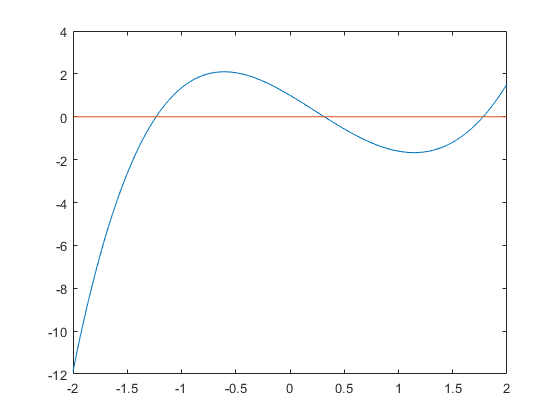

f2 = @(x) x.^3-((x.^2).*exp((-.5).*x))-3.*x+1;
x = linspace(-2,2,101);
zero = x.*0;
y = f2(x);
figure(); plot(x,y,x,zero);

%Zeros in the area of x = -1, 0, 2
fzeroN1 = fzero(f2,-1);
fzero0 = fzero(f2,0);
fzero2 = fzero(f2,2);
disp(' The three roots of this function are ',num2str(fzeroN1),', ',num2str(fzero0),', and ',num2str(fzero2),'.');

 The three roots of this function are -1.2341, 0.31547, and 1.7802.



%%
%Question #3
disp('Question #3:');

Question #3:


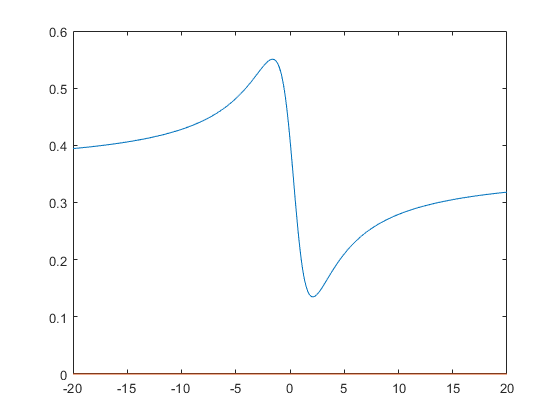


f3 = @(x) (2+(x-1.45).^2)./(3+3.5*(.8*x.^2-.6.*x+2));
f3N = @(x) -1*(2+(x-1.45).^2)./(3+3.5*(.8*x.^2-.6.*x+2));
x = linspace(-20,20,1001);
zero = x.*0;
y = f3(x);
figure(); plot(x,y,x,zero);


% Apparent local minima at 0<x<5, local maxima at -5<x<0.

disp(' The function has apperant maximum on interval -5<x<0');

 The function has apperant maximum on interval -5<x<0


disp('  and mimimum on interval 0<x<5.');

  and mimimum on interval 0<x<5.


%find exact max/min with fmin

fmaxN5_0 = fminbnd(f3N,-5,0);
fmin0_5 = fminbnd(f3,0,5);

disp(' The function has local maximum at x = ',num2str(fmaxN5_0));

 The function has local maximum at x = -1.6096


disp('  and local minimum at x = ',num2str(fmin0_5));

  and local minimum at x = 2.1037



%%
%Question #4
disp('Question #4');

Question #4



%Part a
disp(' Part A');

 Part A


fa = @(x) (x.^3.*exp(-.2.*x))./(1+x.^2);
intA = quadl(fa,1,11);
disp('  Integral from 1 to 11 is ',num2str(intA));

  Integral from 1 to 11 is 14.7474



%Part b
disp(' Part B');

 Part B


fb = @(x) (4.*x+3.*cos(4.*x))./(2+sin(x));
intB = quadl(fb,2,7);
disp('  Integral from 2 to 7 is ',num2str(intB));

  Integral from 2 to 7 is 58.4444



%Part c
disp(' Part C');

 Part C


fc = @(x) sqrt(1+.5.*x.^3-x.^2);
intC = quadl(fc,0,3);
disp('  Integral from 0 to 3 is ',num2str(intC));

  Integral from 0 to 3 is 3.2382



%Part d
disp(' Part D');

 Part D


fd = @(x) (2.*x.^2+x.*cos(x))./(exp(x));
intD = quadl(fd,0,8);
disp('  Integral from 0 to 8 is ',num2str(intD));

  Integral from 0 to 8 is 3.9467
